# CISC 271, Week 7, Day 3: Linear Disciminant Analysis

## Prepare Iris Data - Sepals

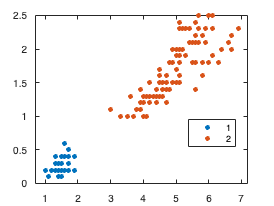

% Load data and extract sepal length and sepal width
load fisheriris
xMat = meas(:,3:4);

% Extract groups
    % the variable "species" contains a cell array of strings with species
    % names. We will make 2 groups:
    % Group 1: setosa
    % Group 2: everything else
yVec = ones(size(species, 1), 1);
yVec(~strcmp(species, 'setosa')) = 2;

%plot the data
gscatter(xMat(:,1), xMat(:,2),yVec)

## Recall k-means performance

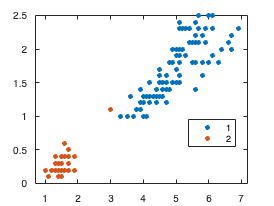

%perform k-means clustering
% Use the builtin function for K-means clustering 
[clustersIris, centroidsIris] = kmeans(xMat, 2);

%Assign colours based on cluster number
%visualize the results
gscatter(xMat(:,1), xMat(:,2), clustersIris)

## Find LDA axis

% Form data matrix A, A1, and A2
A = xMat;
Abar = mean(A)

Abar =     3.7580    1.1993



A1 = A((yVec == 1), :); %extract entries with label 1
A1bar = mean(A1)

A1bar =     1.4620    0.2460



A2 = A((yVec == 2), :);
A2bar = mean(A2);

% Form M1 and M2
M1 = A1 - ones(size(A1, 1), 1)*A1bar;
M2 = A2 - ones(size(A2, 1), 1)*A2bar;

% Find Sw
S1 = M1'*M1;
S2 = M2'*M2;
Sw = S1 + S2

Sw =    68.9542   28.8818
   28.8818   18.4066



% Find Sb
T = [A1bar - Abar; A2bar - Abar]

T =    -2.2960   -0.9533
    1.1480    0.4767


Sb = T'*T;

% Calculate LDA axis as vMAX of Sw^(-1)*Sb
[eigvecs, eigvals] = eig(inv(Sw)*Sb)

eigvecs =     0.9992   -0.3835
   -0.0391    0.9236


eigvals =     0.0956         0
         0   -0.0000


fishersDiscriminant = eigvecs(:,1);


How can we determine how effectively the axis separates our data? 

Similar to PCA scores, we can use the LDA axis to score our data.

## Compute LDA scores

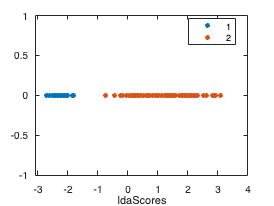

% Bacause we are multiplying the data by a single vector, we are reducing the
% data from 1-2 dimensions

ldaScores = (A - ones(size(A, 1), 1)*Abar)*fishersDiscriminant;

gscatter(ldaScores, zeros(size(A, 1), 1), yVec)

## Repeat for petal length and width (as in lecture video)

NOTE: For simplicity using same variable names after clearing workspace 

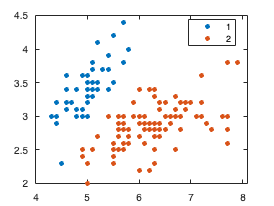

clear
load fisheriris
xMat = meas(:,1:2);

% Exctract groups
    % the variable "species" contains a cell array of strings with species
    % names. We will make 2 groups:
    % Group 1: setosa
    % Group 2: everything else
yVec = ones(size(species, 1), 1);
yVec(~strcmp(species, 'setosa')) = 2;

%plot the data
gscatter(xMat(:,1), xMat(:,2), yVec)


% Form data matrix A, A1, and A2
A = xMat;
Abar = mean(A)

Abar =     5.8433    3.0573



A1 = A((yVec == 1), :); %extract entries with label 1
A1bar = mean(A1)

A1bar =     5.0060    3.4280



A2 = A((yVec == 2), :);
A2bar = mean(A2);

% Form M1 and M2
M1 = A1 - ones(size(A1, 1), 1)*A1bar;
M2 = A2 - ones(size(A2, 1), 1)*A2bar;

% Find Sw
S1 = M1'*M1;
S2 = M2'*M2;
Sw = S1 + S2

Sw =    49.5838   16.9552
   16.9552   18.0024



% Find Sb
T = [A1bar - Abar; A2bar - Abar]

T =    -0.8373    0.3707
    0.4187   -0.1853


Sb = T'*T;

% Calculate LDA axis as vMAX of Sw^(-1)*Sb
[eigvecs, eigvals] = eig(inv(Sw)*Sb)

eigvecs =     0.5483    0.4048
   -0.8363    0.9144


eigvals =     0.0619         0
         0         0


fishersDiscriminant = eigvecs(:,1);

ldaScores = (A - ones(size(A, 1), 1)*Abar)*fishersDiscriminant;

ldaScores =    -0.7778
   -0.4693
   -0.7462
   -0.7174
   -0.9162
   -0.9478
   -0.9683
   -0.7490
   -0.6598
   -0.5529


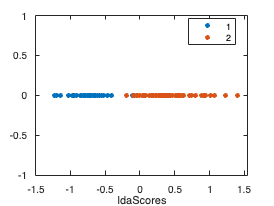

gscatter(ldaScores, zeros(size(A, 1), 1), yVec)

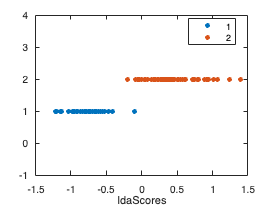

% Q: Why is LDA not finding a hyperplane that can seperate the data,
% including the one "outlier" point, correctly?

% Sometimes it easier to separate the classes as such:
gscatter(ldaScores, ones(size(A, 1), 1).*yVec, yVec)
axis([-1.5, 1.5, -1, 4])
hold on

## How can we use LDA for classification?

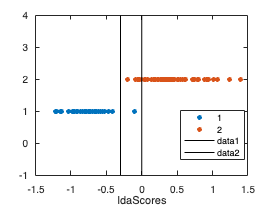

% Since our reduction was supervised, we can use the scores to classify the
% data. We can select a threshold value, t,  such that if the score is >= t
% than it is labelled as group 2, otherwise it is labelled as group 1. 

% Our default threshold tends to be 0, but if but does this work here?
plot([0,0], [-1 4], 'k')

% Let's try -0.3 (all scores >= -0.3 are classified as set 2 and < -0.3
% classified as set 1)
plot([-0.3,-0.3], [-1, 4], 'k') % threshold of -0.3

hold off


% Another option is to use the scores themselves as potential thresholds
% and calculate accuracies to see which works best (this is what you will
% do in A4)




## We can Visualize LDA axis on the zero-mean data

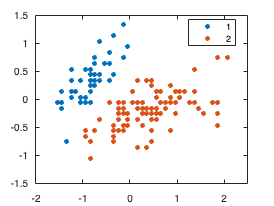

M = A - Abar;
gscatter(M(:,1), M(:,2), yVec)

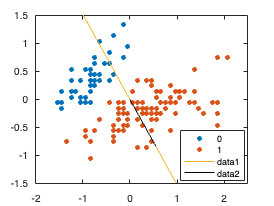

gscatter(M(:,1), M(:,2),ldaScores>=-0.3)
hold on
%find variables for equation of a line y=mx+b
m = fishersDiscriminant(2)/fishersDiscriminant(1); 
b = 0; %because we are working with the zero-mean data our eigenvectors stem from (0,0)
f1 = m*(-2)+b;
f2 = m*2.5+b;
plot([-2, 2.5], [f1, f2]) %plot axis (extended vMAX)
% plot only vMAX (not extended)
plot([0, fishersDiscriminant(1)], [0, fishersDiscriminant(2)], 'k');
axis([-2 2.5 -1.5 1.5])